# **Control usando estimación de estados**

Agregue un controlador en espacio de estados al sistema del ejercicio 3.

**1)** Varíe en un 10% al menos 3 parámetros del modelo y en 5% los restantes 3 parámetros. 

close all; clear all; clc;
% Parámetros del sistema.
mc=401;                         % Quarter car mass [kg]
mw=48;                          % Wheel mass [kg]
ds=2200;                        % Suspension damping coefficient [Ns/m]
cs=23000;                       % Suspension spring coefficient [N/m]
cw=250000;                      % Wheel spring coefficient [N/m]
tau=0.001;                      % Actuator time constant [s]

% Matrices del sistema.
A=[0            1      0      0      0;
   -(cw+cs)/mw -ds/mw  cs/mw  ds/mw -1/mw;
   0            0      0      1      0;
   cs/mc        ds/mc -cs/mc -ds/mc  1/mc;
   0            0      0      0     -1/tau]

A = 1.0e+03 *

         0    0.0010         0         0         0
   -5.6875   -0.0458    0.4792    0.0458   -0.0000
         0         0         0    0.0010         0
    0.0574    0.0055   -0.0574   -0.0055    0.0000
         0         0         0         0   -1.0000



B=[0 0 0 0 1/tau]';
H=[0 cw/mw 0 0 0]';
C=[-1    0      1      0     0];

% Variación de parámetros.
mc = 1.1*mc;
mw = 1.1*mw;
ds = 1.1*ds;
cs = 1.05*cs;
cw = 1.05*cw;
tau = 1.05*tau;

% Matrices del observador.
A_tilde=[0            1      0      0      0;
         -(cw+cs)/mw -ds/mw  cs/mw  ds/mw -1/mw;
         0            0      0      1      0;
         cs/mc        ds/mc -cs/mc -ds/mc  1/mc;
         0            0      0      0     -1/tau];
B_tilde=[0 0 0 0 1/tau]';
C_tilde=[-1    0      1      0     0];

I = eye(6);

**2)** Determine el polinomio deseado para un overshoot del 2% y un settling time de 0.5 s para la variable de salida del sistema.

A partir de considerar polos complejos conjugados para un sistema de segundo orden, partiremos de una estimación inicial de parámetros hasta encontrar los parámetros deseados. Los polos restante los colocaremos lejos para que no interfiera en la respuesta.

Entonces, según una serie de expresiones, podemos decir que:


$$\zeta =\frac{\ln \left(M_p \right)}{\sqrt{\pi^2 +{\left(\ln \left(M_p \right)\right)}^2 }}$$



$$\omega_n \approx \frac{4}{\zeta T_s }$$


Para este caso:


$$\begin{array}{l}
\zeta =0\ldotp 779\\
\omega_n =10,27\;\textrm{rad}/s
\end{array}$$


syms s % Variable compleja.
%zeta = 0.779;
zeta = 0.7; % Amortiguamiento -> Obtenido de prueba y error a mano.
wn0 = 10.27; % Frecuencia natural incial.
% Asumimos que tendremos acción integral.
disp('El polinomio deseado del sistema es:')

El polinomio deseado del sistema es:


p_deseado = (s^2 + 2*wn0*zeta*s + wn0^2)*(s + 2*wn0*zeta)*(s + 3*zeta*wn0)*(s + 4*zeta*wn0)*(s + 5*zeta*wn0); % Polinomio deseado.
coef_deseado = coeffs(p_deseado, s); % Coeficientes simbólicos del polinomio anterior.
coef_deseado_double = double(coef_deseado); % Coeficientes en formato double.
Ha = tf([1],[coef_deseado_double(1,7) coef_deseado_double(1,6) coef_deseado_double(1,5) coef_deseado_double(1,4) coef_deseado_double(1,3) coef_deseado_double(1,2) coef_deseado_double(1,1)]); % Función de transferencia.
sa = stepinfo(Ha) % Buscamos las especificaciones de diseño del sistema.

sa = struct with fields:
         RiseTime: 0.2948
    TransientTime: 0.7157
     SettlingTime: 0.7157
      SettlingMin: 2.6695e-08
      SettlingMax: 3.0202e-08
        Overshoot: 2.1015
       Undershoot: 0
             Peak: 3.0202e-08
         PeakTime: 0.6822


Dado que el settling time del sistema resulta mayor al deseado, aumetamos la frecuencia angular del sistema hasta obtener el valor deseado.

settlingtime = 0.5;
wn = wn0;
while(abs(sa.SettlingTime-settlingtime)>0.01)
    wn = wn + 0.01;
    p_deseado = (s^2 + 2*wn*zeta*s + wn^2)*(s + 2*wn*zeta)*(s + 3*zeta*wn)*(s + 4*zeta*wn)*(s + 5*zeta*wn);
    coef_deseado = coeffs(p_deseado, s); 
    coef_deseado_double = double(coef_deseado); 
    Ha = tf([1],[coef_deseado_double(1,7) coef_deseado_double(1,6) coef_deseado_double(1,5) coef_deseado_double(1,4) coef_deseado_double(1,3) coef_deseado_double(1,2) coef_deseado_double(1,1)]); 
    sa = stepinfo(Ha); 
end
disp('El nuevo valor de frecuencia natural es:')

El nuevo valor de frecuencia natural es:


wn

wn = 14.4200

disp('Los polos del polinomio deseado son:')

Los polos del polinomio deseado son:


disp(pole(Ha))

 -50.4700 + 0.0000i
 -40.3760 + 0.0000i
 -30.2820 + 0.0000i
 -20.1880 + 0.0000i
 -10.0940 +10.2979i
 -10.0940 -10.2979i



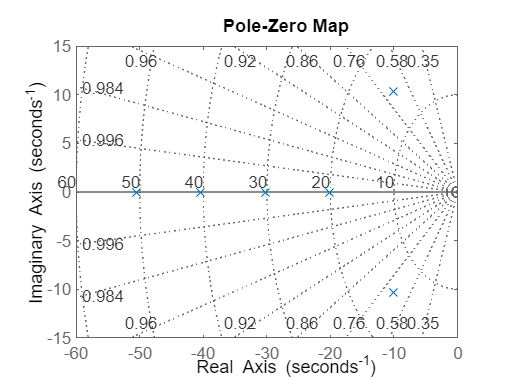

pzmap(Ha) % Graficamos los polos y ceros en el plano de Laplace.
grid on

ha = stepplot(Ha) % Respuesta al escalón unitario.


ha =

	resppack.timeplot



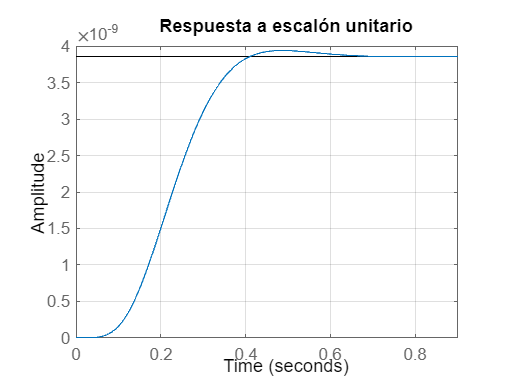

setoptions(ha,'Grid','on');
title('Respuesta a escalón unitario')

sa

sa = struct with fields:
         RiseTime: 0.2100
    TransientTime: 0.5097
     SettlingTime: 0.5097
      SettlingMin: 3.4839e-09
      SettlingMax: 3.9416e-09
        Overshoot: 2.1015
       Undershoot: 0
             Peak: 3.9416e-09
         PeakTime: 0.4859



% Coeficientes del polinomio deseado.
p6 = coef_deseado_double(1,1);
p5 = coef_deseado_double(1,2);
p4 = coef_deseado_double(1,3);
p3 = coef_deseado_double(1,4);
p2 = coef_deseado_double(1,5);
p1 = coef_deseado_double(1,6);

**3)** Agrege acción integral al controlador.

% Nuevas matrices del sistema con acción integral.
Aaug = [A zeros(5,1);
        C 0];
Baug = [B;0];
Caug = [C 0];
Faug = [zeros(5,1);-1];

**4)** Cierre el bucle de control a través del observador. Encuentre el valor de la matriz K.

disp('Polinomio característico:')

Polinomio característico:


p_caracteristico = expand(det(s*I-Aaug))

$$p\_caracteristico = s^{6}+\frac{2529475\,s^{5}}{2406}+\frac{137297125\,s^{4}}{2406}+\frac{6945437500\,s^{3}}{1203}+\frac{11578125000\,s^{2}}{401}+\frac{359375000000\,s}{1203}$$

coef_caracteristico = coeffs(p_caracteristico,s); % Obtenemos los coeficientes simbólicos del polinomio característico.
coef_caracteristico_double = double(coef_caracteristico); % Coeficientes formato double.
% Coeficientes del polinomio característico.
a6 = 0;
a5 = coef_caracteristico_double(1,1);
a4 = coef_caracteristico_double(1,2);
a3 = coef_caracteristico_double(1,3);
a2 = coef_caracteristico_double(1,4);
a1 = coef_caracteristico_double(1,5);
% Formula de Ackermann.
Wr = [Baug Aaug*Baug Aaug^2*Baug Aaug^3*Baug Aaug^4*Baug Aaug^5*Baug]; % Matriz de alcanzabilidad.
Wr_tilde = inv([1 a1 a2 a3 a4 a5;
                0 1  a1 a2 a3 a4;
                0 0  1  a1 a2 a3; 
                0 0  0  1  a1 a2; 
                0 0  0  0  1  a1; 
                0 0  0  0  0  1])

Wr_tilde = 1.0e+15 *

    0.0000   -0.0000    0.0000   -0.0000    0.0010   -1.0478
         0    0.0000   -0.0000    0.0000   -0.0000    0.0010
         0         0    0.0000   -0.0000    0.0000   -0.0000
         0         0         0    0.0000   -0.0000    0.0000
         0         0         0         0    0.0000   -0.0000
         0         0         0         0         0    0.0000


K = [p1-a1 p2-a2 p3-a3 p4-a4 p5-a5 p6-a6]*Wr_tilde*inv(Wr)

K = 1.0e+04 *

    1.5964    0.0072    0.1938    0.0157   -0.0001    1.9944



% Corroboramos.
Kprima = acker(Aaug,Baug,pole(Ha))

Kprima = 1.0e+04 *

    1.5964    0.0072    0.1938    0.0157   -0.0001    1.9944


% Establecemos los polos del observador como 5 veces más rapidos que los
% polos dominantes del sistema a lazo cerrado. Alejamos el resto.
disp('Polinomio deseado del observador a lazo cerrado:')

Polinomio deseado del observador a lazo cerrado:


tfobsv_dom = tf([1],[1 2*zeta*wn wn^2],1); % Función de transferencia con polos dominantes, segundo orden.
polos_dom_obsv = 5*pole(tfobsv_dom)

polos_dom_obsv =  -50.4700 +51.4897i
 -50.4700 -51.4897i


p_deseado = (s - polos_dom_obsv(1))*(s - polos_dom_obsv(2))*(s + 4*zeta*wn)^4

$$p\_deseado = \left(s+\frac{5047}{100}-\frac{7246530909180679}{140737488355328}\,\mathrm{i}\right)\,\left(s+\frac{5047}{100}+\frac{7246530909180679}{140737488355328}\,\mathrm{i}\right)\,{\left(s+\frac{5047}{125}\right)}^{4}$$

coef_obs_deseado = coeffs(p_deseado, s); % Coeficientes del polinomio deseado.

syms l1 l2 l3 l4 l5 l6
L = [l1 l2 l3 l4 l5 l6]'; % Matriz de ganancia del obsv. a lazo cerrado.
p_observador = simplify(det(s*I - Aaug + L*Caug));
coef_obs = coeffs(p_observador, s); % Coeficientes del polinomio del observador.

% Igualamos los coeficientes.
eqns = [coef_obs == coef_obs_deseado(2:end)];

% Resolvemos las ecuaciones.
sol = solve(eqns, [l1, l2, l3, l4, l5, l6]);

% Mostramos los coeficientes resultantes.
disp("Las ganancias del observador son:");

Las ganancias del observador son:


l1_double = double(sol.l1);
l2_double = double(sol.l2);
l3_double = double(sol.l3);
l4_double = double(sol.l4);
l5_double = double(sol.l5);
l6_double = double(sol.l6);
disp('l1:')

l1:


disp(l1_double);

  -3.2854e+10



disp('l2:')

l2:


disp(l2_double);

     0



disp('l3:')

l3:


disp(l3_double);

  716.5193



disp('l4:')

l4:


disp(l4_double);

  -7.1706e+05



disp('l5:')

l5:


disp(l5_double);

  -72.3563



disp('l6:')

l6:


disp(l6_double);

   8.6516e+04




L = [l1_double l2_double l3_double l4_double l5_double l6_double]';

% Corroboramos:
Lprima = acker(Aaug',Caug',[polos_dom_obsv(2) polos_dom_obsv(1) -4*zeta*wn -4*zeta*wn -4*zeta*wn -4*zeta*wn])'

Lprima =    NaN
   NaN
   NaN
   NaN
   NaN
   Inf


**5)** Determine el valor de kr.

kr = -1/(Caug*inv(Aaug-Baug*K)*Baug)

kr = 1.3433e+20